Read the text file with the fluorescence data obtained from ImageJ into MATLAB as a matrix of data, then transpose the data.

rawData = (readmatrix('Results.txt'))';

rawData = 	1.0e+03 *

    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500
    1.4202    1.3301    1.2391    1.1493    1.0802    1.2274    1.4642    1.6815    2.0056    2.0807    1.9415    1.9021    1.7965    1.6817    1.5496    1.6768    2.7262    3.0808    2.8011    3.4986    3.5437    3.6510    3.5197    3.5704    3.4966    3.3819    3.3880    3.3896    3.2322    3.1410    3.0966    3.3555    3.4719    3.3833    3.2486    3.0528    2.8380    2.5893    2.3133    2.0694    1.9414    1.9013    1.7890    1.7292    1.6673    1.4910    2.0855    2.8

Now we have a matrix that contains our fluorescence values. Check the number of rows and columns of this matrix using the size function.

rows = size(rawData,1)

rows = 74

cols = size(rawData,2)

cols = 2184

The first row of our rawData matrix does not contain fluorescence data, so we will remove it. Write code that indexes the `rawData` matrix by selecting ALL other rows except the first one, and stores the values into a new matrix `rawF`.

rawF = rawData(2:end,:);

rawF = 	1.0e+03 *

    1.4202    1.3301    1.2391    1.1493    1.0802    1.2274    1.4642    1.6815    2.0056    2.0807    1.9415    1.9021    1.7965    1.6817    1.5496    1.6768    2.7262    3.0808    2.8011    3.4986    3.5437    3.6510    3.5197    3.5704    3.4966    3.3819    3.3880    3.3896    3.2322    3.1410    3.0966    3.3555    3.4719    3.3833    3.2486    3.0528    2.8380    2.5893    2.3133    2.0694    1.9414    1.9013    1.7890    1.7292    1.6673    1.4910    2.0855    2.8672    3.2732    3.0091
    1.3074    1.4144    1.4148    1.3571    1.4003    1.6093    2.0509    2.0642    1.9432    1.9674    2.0127    2.0141    2.0798    2.1022    1.9893    2.0135    1.9022    1.9256    1.8108    1.8155    1.8770    1.8331    1.7900    1.8431    1.9013    1.7063    1.5804    1.4952    1.4180    1.3348    1.3205    1.9144    2.2368    2.0896    1.9081    1.6588    1.5043    1.3676    1.2887    1.2092    1.1625    1.3182    1.3678    1.3998    1.2867    1.2248    1.4499    1.7124

Calculate DF/F for one cell ((F_raw - F_baseline)/F_baseline) and store it in a vector named `dff_cell`. To visualize your results, plot the raw fluorescence trace **and **the DF/F of your cell as two different figures.

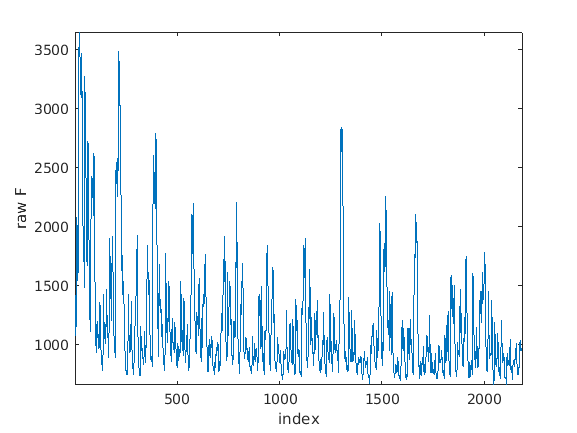

cell = 1; % this is the cell we will extract
rawF_cell = rawF(cell,:);

% round to nearest multiple of 10
rawF_rounded = round(rawF_cell/10)*10; 
baseline = mode(rawF_rounded);

% calculate df/f
dff_cell = (rawF_cell-baseline)/baseline;

        
figure()
plot(1:size(rawF_cell,2),rawF_cell)
xlabel('index')
ylabel('raw F')
axis tight        

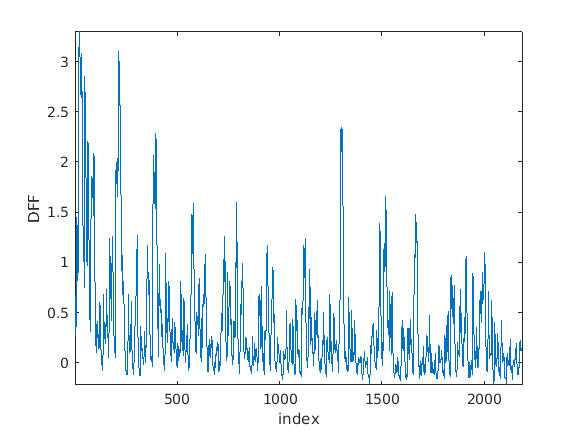

        
figure()
plot(1:size(rawF_cell,2),dff_cell)
xlabel('index')
ylabel('DFF')
axis tight

Generate a matrix that contains the DF/F values for all cells. This matrix `DFF` should be the same size as the `rawF` matrix.

rawF_rounded = round(rawF/10)*10;
baseline = mode(rawF_rounded,2);
DFF = (rawF-baseline)./baseline;